clear
close all
syms x n
f=x^2;
a=-1;
b=1;
L=1;
N=4;
a0=1/L*int(f,x,-L,L);
an=1/L*int(f*cos(pi*x*n/L),x,-L,L);
bn=1/L*int(f*sin(n*pi*x/L),x,-L,L);

Furje=a0/2;

for i=1:N
    Furje=Furje+subs(an,n,i)*cos(pi*i*x/L)+subs(bn,n,i)*sin(pi*i*x/L);
end
Furje

$$Furje = \frac{\cos\left(2\,\pi \,x\right)}{\pi^{2}}-\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}-\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}+\frac{\cos\left(4\,\pi \,x\right)}{4\,\pi^{2}}+\frac{1}{3}$$

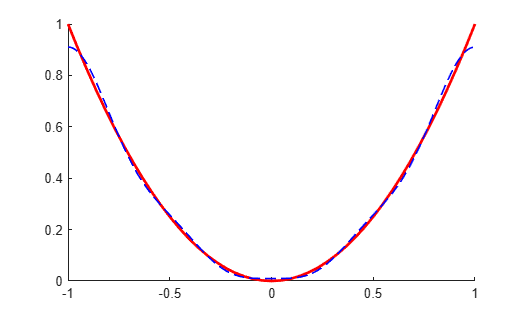

$$Furje = \frac{\cos\left(2\,\pi \,x\right)}{\pi^{2}}-\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}-\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}+\frac{\cos\left(4\,\pi \,x\right)}{4\,\pi^{2}}+\frac{1}{3}$$

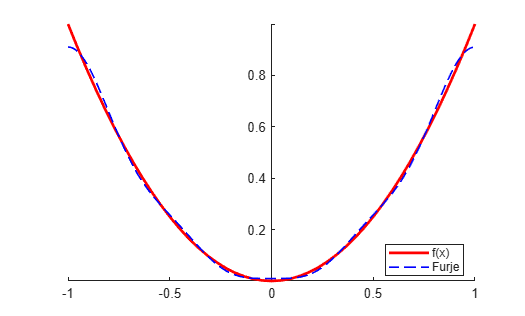

hold on
fplot(f,[a,b],'LineWidth',2,'Color','r')
fplot(Furje,[a,b],'--','LineWidth',1.2,'Color','b')